close all
clear all

G = tf(292.4,[1 3.367 0]) % Planta de posición del motor


G =
 
      292.4
  -------------
  s^2 + 3.367 s
 
Continuous-time transfer function.
Model Properties


% En espacio de estados:
A = [0 1
    0 -3.367]

A =          0    1.0000
         0   -3.3670


B = [0
    292.4]

B =          0
  292.4000


C = [1 0]

C =      1     0


%Parámetros de diseño
Tes = 1.5; % 2 segundos
Mp = 0.05; % 5%

% Factor de amortiguamiento relativo
far = -log(Mp)/sqrt(pi^2 + log(Mp)^2)

far = 0.6901


sigma = 4/Tes

sigma = 2.6667

wn = sigma/far

wn = 3.8641

fi = acos(far)

fi = 0.8092

% Tiempo de subida
Tr = exp(fi/tan(fi))/wn

Tr = 0.5598

% Tr = 1.1196

T = 0.1; % Tiempo de muestreo
% Muestreo del sistema
FI = eye(2)*T + A*T^2/2 + A^2*T^3/6 + A^3*T^4/24

FI =     0.1000    0.0045
         0    0.0849


G = eye(2) + A*FI

G =     1.0000    0.0849
         0    0.7142


H = FI*B

H =     1.3117
   24.8234


% Servosistema agregando integrador
GN = [G zeros(2, 1)
    -C*G 1]

GN =     1.0000    0.0849         0
         0    0.7142         0
   -1.0000   -0.0849    1.0000


HN = [H
    -C*H]

HN =     1.3117
   24.8234
   -1.3117



% Controlabilidad
CoN = [HN GN*HN GN^2*HN]

CoN =     1.3117    3.4191    4.9241
   24.8234   17.7278   12.6605
   -1.3117   -4.7308   -9.6550


det_CoN = det(CoN)

det_CoN = 152.9624

% det_CoN = 2.0323e3 != 0 -> Controlable

% Dinámica deseada
wd = -pi*sigma/log(Mp)

wd = 2.7965

s1 = -sigma + wd*1i

s1 = -2.6667 + 2.7965i

s2 = -sigma - wd*1i

s2 = -2.6667 - 2.7965i

s3 = -5*sigma

s3 = -13.3333


% Polos discretos
z1 = exp(T*s1)

z1 = 0.7362 + 0.2114i

z2 = exp(T*s2)

z2 = 0.7362 - 0.2114i

z3 = exp(T*s3)

z3 = 0.2636



% Diseño
KN = acker(GN, HN, [z1 z2 z3])

KN =     0.1508    0.0296   -0.0339


K2 = KN(1:2)

K2 =     0.1508    0.0296


K1 = -KN(3)

K1 = 0.0339

## PRUEBAS

sp100 = [0.00  3.39  0.00  0.00
100.00  4.64  49.61  3.66
200.00  4.80  98.19  12.66
300.00  4.29  138.21  25.03
400.00  3.49  161.71  39.38
500.00  2.58  161.79  55.69
600.00  1.20  163.11  70.87
700.00  0.89  122.64  84.37
800.00  0.77  84.87  93.94
900.00  0.67  56.47  100.12
1000.00  0.59  36.29  103.78
1100.00  0.41  22.30  106.31
1200.00  0.25  13.39  107.44
1300.00  0.07  10.94  107.44
1400.00  -0.18  10.91  107.44
1500.00  -0.43  10.91  107.44
1600.00  -0.68  10.91  107.44
1700.00  -0.94  10.91  107.44
1800.00  -1.19  10.91  107.44
1900.00  -1.44  10.91  107.44
2000.00  -1.69  10.91  107.44
2100.00  -1.94  10.91  107.44
2200.00  -1.66  -2.07  106.59
2300.00  -0.18  -38.36  103.22
2400.00  -0.16  -25.37  100.41
2500.00  -0.38  -14.76  99.84
2600.00  -0.39  -14.16  99.84
2700.00  -0.39  -14.15  99.84
2800.00  -0.38  -14.15  99.84
2900.00  -0.38  -14.15  99.84
3000.00  -0.37  -14.15  99.84
];

sp120 = [0.00  4.07  0.00  0.00
100.00  6.15  46.08  3.66
200.00  7.28  88.89  11.81
300.00  8.32  112.54  22.22
400.00  8.83  128.23  35.16
500.00  9.09  134.78  48.09
600.00  8.56  141.79  63.00
700.00  7.17  162.71  77.62
800.00  6.30  147.84  92.53
900.00  3.85  165.46  108.00
1000.00  1.65  158.70  123.19
1100.00  -0.18  129.20  137.25
1200.00  -0.96  78.00  146.53
1300.00  -1.03  30.55  149.62
1400.00  -1.29  8.90  149.06
1500.00  -1.51  -9.92  147.94
1600.00  -1.81  -19.46  145.97
1700.00  -1.65  -35.19  142.87
1800.00  -1.44  -42.18  138.66
1900.00  -1.23  -42.65  134.16
2000.00  -1.12  -37.98  130.22
2100.00  -1.08  -31.95  127.12
2200.00  -0.94  -27.03  124.31
2300.00  -0.84  -21.44  122.06
2400.00  -0.75  -16.34  120.37
2500.00  -0.75  -11.58  119.53
2600.00  -0.67  -8.28  118.69
2700.00  -0.63  -6.36  118.41
2800.00  -0.59  -5.89  118.41
2900.00  -0.54  -5.88  118.41
3000.00  -0.48  -5.88  118.41
% 3100.00  -0.43  -5.88  118.41
% 3200.00  -0.38  -5.88  118.41
% 3300.00  -0.32  -5.88  118.41
% 3400.00  -0.27  -5.88  118.41
% 3500.00  -0.21  -5.88  118.41
% 3600.00  -0.16  -5.88  118.41
% 3700.00  -0.11  -5.88  118.41
% 3800.00  -0.05  -5.88  118.41
% 3900.00  0.00  -5.88  118.41
% 4000.00  0.06  -5.88  118.41
% 4100.00  0.11  -5.88  118.41
% 4200.00  0.16  -5.88  118.41
% 4300.00  0.22  -5.88  118.41
];

SP50 = [0.00  1.70  0.00  0.00
100.00  2.85  11.23  1.12
200.00  2.45  52.71  5.62
300.00  1.95  74.69  12.94
400.00  1.71  76.08  20.81
500.00  1.70  65.95  27.84
600.00  1.62  57.28  33.75
700.00  1.40  49.98  39.09
800.00  1.18  41.91  43.59
900.00  1.13  31.53  46.69
1000.00  1.03  22.75  49.22
1100.00  0.92  16.89  50.91
1200.00  0.80  12.91  52.03
1300.00  0.77  8.24  52.59
1400.00  0.71  7.36  52.59
1500.00  0.62  7.35  52.59
1600.00  0.53  7.35  52.59
1700.00  0.44  7.35  52.59
1800.00  0.35  7.35  52.59
1900.00  0.27  7.35  52.59
2000.00  0.18  7.35  52.59
2100.00  0.09  7.35  52.59
2200.00  0.00  7.35  52.59
2300.00  -0.09  7.35  52.59
2400.00  -0.17  7.35  52.59
2500.00  -0.26  7.35  52.59
2600.00  -0.35  7.35  52.59
2700.00  -0.44  7.35  52.59
2800.00  -0.53  7.35  52.59
2900.00  -0.61  7.35  52.59
3000.00  -0.70  7.35  52.59
% 3100.00  -0.70  6.18  52.31
% 3200.00  -0.78  6.11  52.31
];

SP80 = [0.00  2.71  0.00  0.00
100.00  3.34  47.56  3.66
200.00  2.88  96.05  12.66
300.00  1.87  130.64  24.75
400.00  1.41  128.45  37.69
500.00  1.70  100.59  48.38
600.00  1.23  93.10  57.94
700.00  0.84  78.81  66.37
800.00  0.83  56.07  72.56
900.00  0.73  39.88  77.06
1000.00  0.64  28.89  79.87
1100.00  0.49  20.05  82.12
1200.00  0.40  13.71  83.25
1300.00  0.39  8.49  83.53
1400.00  0.28  8.25  83.53
1500.00  0.16  8.25  83.53
1600.00  0.04  8.25  83.53
1700.00  -0.08  8.25  83.53
1800.00  -0.20  8.25  83.53
1900.00  -0.32  8.25  83.53
2000.00  -0.44  8.25  83.53
2100.00  -0.56  8.25  83.53
2200.00  -0.68  8.25  83.53
2300.00  -0.80  8.25  83.53
2400.00  -0.92  8.25  83.53
2500.00  -0.96  7.11  83.25
2600.00  -0.11  -14.56  81.56
2700.00  -0.02  -16.04  81.00
2800.00  -0.05  -15.95  81.00
2900.00  -0.09  -15.95  81.00
3000.00  -0.12  -15.95  81.00
% 3100.00  -0.16  -15.95  81.00
% 3200.00  -0.19  -15.95  81.00
% 3300.00  -0.22  -15.95  81.00
];

t1 = sp100(:, 1);
u1 = sp100(:, 2);
v1 = sp100(:, 3);
x1 = sp100(:, 4);

t2 = SP80(:, 1);
u2 = SP80(:, 2);
v2 = SP80(:, 3);
x2 = SP80(:, 4);

t3 = sp120(:, 1);
u3 = sp120(:, 2);
v3 = sp120(:, 3);
x3 = sp120(:, 4);

t4 = SP50(:, 1);
u4 = SP50(:, 2);
v4 = SP50(:, 3);
x4 = SP50(:, 4);

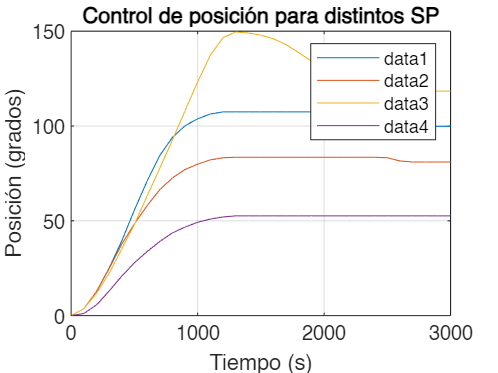

figure(1)
hold off
grid on

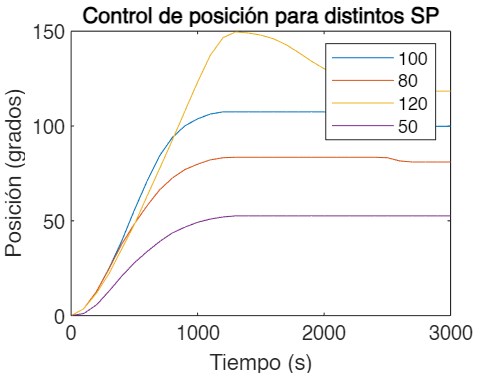

plot(t1, x1)
hold on
plot(t2, x2)
plot(t3, x3)
plot(t4, x4)
title("Control de posición para distintos SP")
ylabel("Posición (grados)")
xlabel("Tiempo (s)")
legend("100", "80", "120", "50")